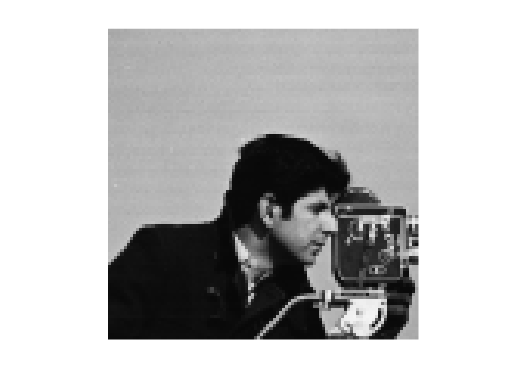

A=im2gray(imread("cameraman.tif"));
A=A(4:103,59:158);
images = cell(1,3);
% figure
for i = 1:3;images{i} = A;end
figure
imshow(A)

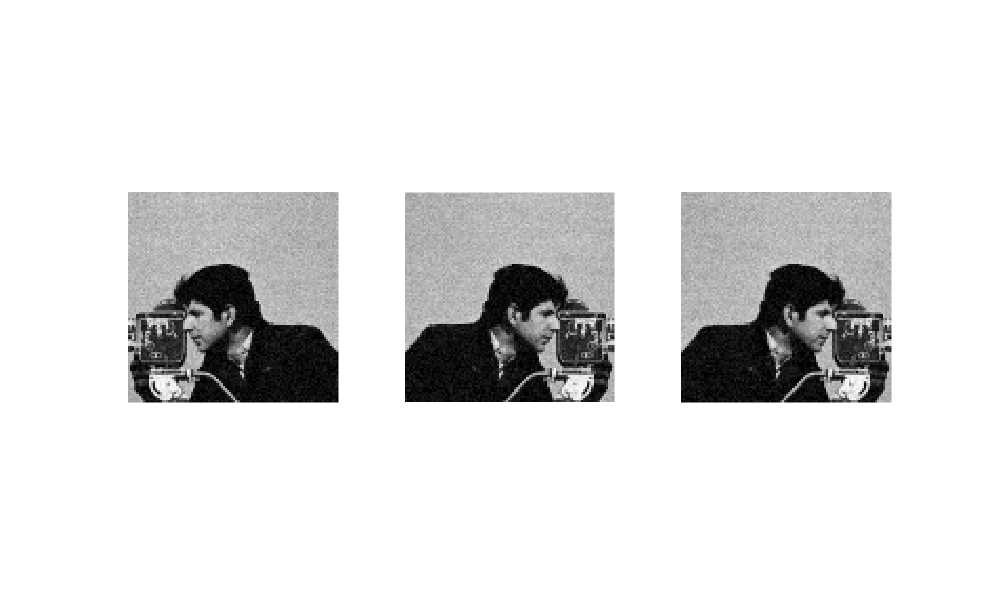

% Define the percentage of images to apply transformations to
transformation_percentage = 50; % You can adjust this percentage as needed

% Shuffle the images
rng('shuffle'); % Seed the random number generator with the current time
shuffled_indices = randperm(numel(images));

% Calculate the number of images to apply transformations to
num_images = numel(images);
num_transform_images =  num_images;

% Apply transformations to randomly selected images
transform_indices = shuffled_indices(1:num_transform_images);
for i = 1:num_transform_images
    % Apply transformations
    img = images{transform_indices(i)};
    
    % Randomly flip
    if rand < 0.5
        img = flip(img, 2); % Randomly flip horizontally or vertically
    end
    

    
    % Add noise
    
        % Add Gaussian noise
        noise_amount = 0.0011; % Adjust noise amount as needed
        img = imnoise(img, 'gaussian', 0, noise_amount);
    
    
    images{transform_indices(i)} = img; % Update transformed image
end

figure;
set(gcf, 'Position', get(0, 'Screensize'));
% Loop to plot images
for i = 1:3
    % Calculate subplot position
    subplot(1,3,i)

    % Plot image
  
    imshow(images{i});
    axis off; % Turn off axis
end

X=[];
for i= 1:3
X=[X;reshape(images{i},1,[])];
end

[U,S,V]=svd(double(X));


X_new=double(X)*V;
total_var=sum(var(X_new,0,1));
columns=size(X);

summation=0;
V_top_k=[];
for i=1: columns(2)
    summation=summation+ var(double(X_new(:,i)));
    V_top_k=[V_top_k, V(:,i)];
    if ((summation/total_var*100)>=10)
        break
    end
end

size(V_top_k)

ans =        10000           2


X_transformed=double(X)*V_top_k;

size(X_transformed)

ans =      3     2


X_reconstructed=X_transformed(2,:)*V_top_k';
figure

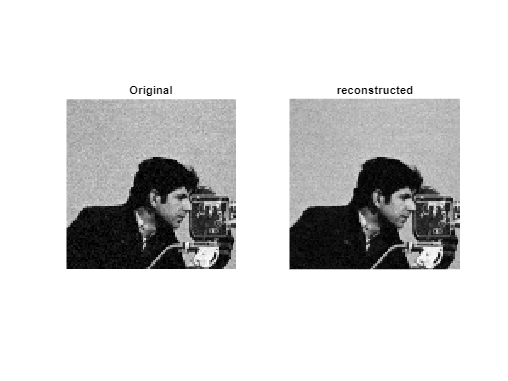

immm = mat2gray(reshape(X_reconstructed,100,100));
subplot(1,2,1)
imshow(images{2})
title('Original')
subplot(1,2,2)
imshow(immm)
title('reconstructed')